clear; clc; close all;
rng(275); % Note that the analysis in this study is reproducible for the random seed (rng) value of rng(275).
          % You can still change the seed and try different random scenarios and do your own analysis.

# An Illustrative Example

## Scenario Environment

This example is designed to compare the results of $2$-D assignment and $S$-D assignment algorithms in restart architecture.  Since the application is developed in restart architecture, all the examples under this heading take place in only one time frame. First of all, in the scenario, there are $3$-sensors $5$-targets. The ground truth information showing the positions of the targets at the time is generated as below:

targetPositionGroundTruth = [-100, 0; ...
                              -50, 0; ...
                                0, 0; ...
                               50, 0; ...
                              100, 0];

We visualize the ground truth by drawing target positions. 

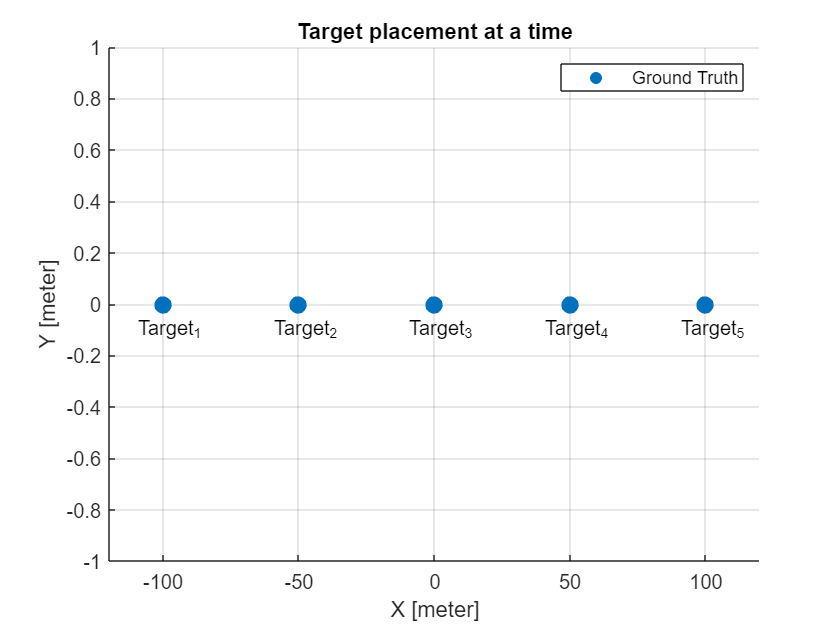

figure;
scatter(targetPositionGroundTruth(:, 1), targetPositionGroundTruth(:, 2), 75, "filled")
xlim([-120, 120]);
ylim([-1, 1])
grid on
legend("Ground Truth")
text(targetPositionGroundTruth(:, 1) - 10, targetPositionGroundTruth(:, 2) - 0.1, ["Target_1", "Target_2", "Target_3", "Target_4", "Target_5"]);
title("Target placement at a time")
xlabel("X [meter]")
ylabel("Y [meter]")

In order to roughly simulate the positions of the tracks obtained from the local trackers, let's simply add normally distributed random noise to the ground truth positions. 

localTracks = cell(3, 1);
stateCov = 100 * eye(2);
for i = 1:3     % 3-sensor
    noisyPositions = mvnrnd(targetPositionGroundTruth, stateCov);
    for j = 1:5 % 5-target
        localTracks{i}(j, 1) = struct("State", noisyPositions(j, :)', ... 
                                      "StateCovariance", stateCov, ...
                                      "ID", string(char(j + 64)));
    end 
end
for i = 1:3     % 3-sensor
    localTracks{i} = localTracks{i}(randperm(length(localTracks{i})));
end

The figure below shows the $3$ local tracks for each target coming from $3$ different sensors.

figure;
colorPalette = [0.4660, 0.6740, 0.1880; ...
                0.8500, 0.3250, 0.0980; ...
                0.6350, 0.0780, 0.1840];
scatter(targetPositionGroundTruth(:, 1), targetPositionGroundTruth(:, 2), 75, "filled")
hold on
for i = 1:3     % 3-sensor
    for j = 1:5 % 5-target
        scatter(localTracks{i}(j).State(1), localTracks{i}(j).State(2), 30, colorPalette(i, :), "filled")
    end
end
legend(["Ground Truth", strings(1, 4), "Sensor_1 Tracks", strings(1, 4), "Sensor_2 Tracks", strings(1, 4), "Sensor_3 Tracks", strings(1, 4)]);

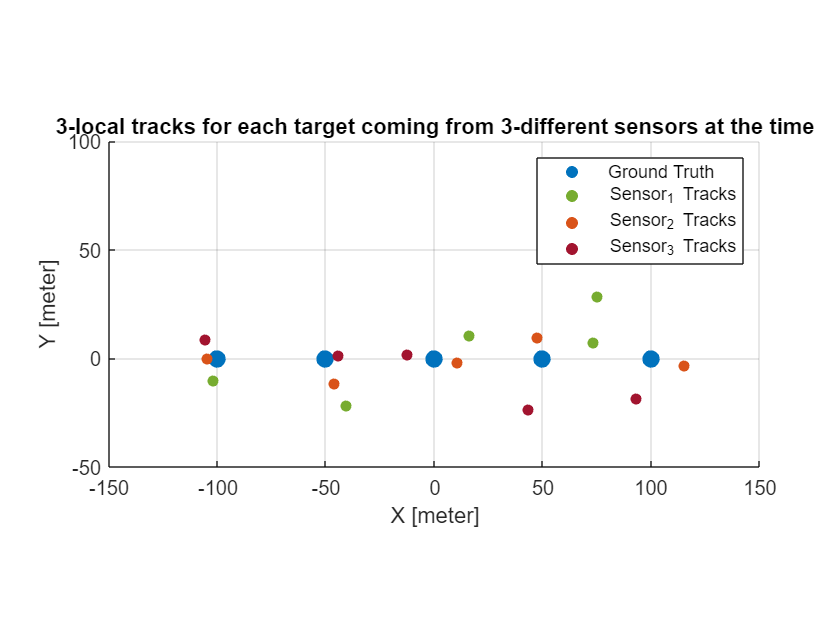

axis equal
xlim([-150, 150])
ylim([-50, 100])
grid on
title("3-local tracks for each target coming from 3-different sensors at the time")
xlabel("X [meter]")
ylabel("Y [meter]")

## Cost Function

The cost function we will use throughout all the study is as follows [1]:


$$\ell\big(\tau\big) =  -\sum_{i = 1}^S\ln\Bigg(\frac{1}{|2\pi R_{ii}|^{0.5}}\Bigg) -\Bigg(\frac{1}{2}\big(x_i - x_{f,S}\big)^TR_{ii}^{-1}\big(x_i-x_{f, S}\big)\Bigg)$$


where $\tau$ is a hypothesis and $\ell\big(\tau\big)$ is the negative loglikelihood ratio of the hypothesis and,


$$x_{f, S} = R_{f, S}\sum_{i = 1}^S R_{ii}^{-1}x_i$$



$$R_{f, S} = \Bigg(\sum_{i = 1}^SR_{ii}^{-1}\Bigg)^{-1}$$


whereas $R_{ii}$ is the state error covariance matrix of related track and $S$ is the list number. Note that the cost function in $2$-D assignment is always a $2$-D matrix, while in higher dimensions is a $S$-dimensional matrix representation.

## Balanced List

Let's consider an ideal scenario where all $3$ sensors observe the same surveillance area and have the same field of view, so each target can be observed by each sensor and there are no uncertainties such as missed detection, unresolved target, etc. In this case, we can create a sensor$-$track list as in the Figure 1.

Figure 1

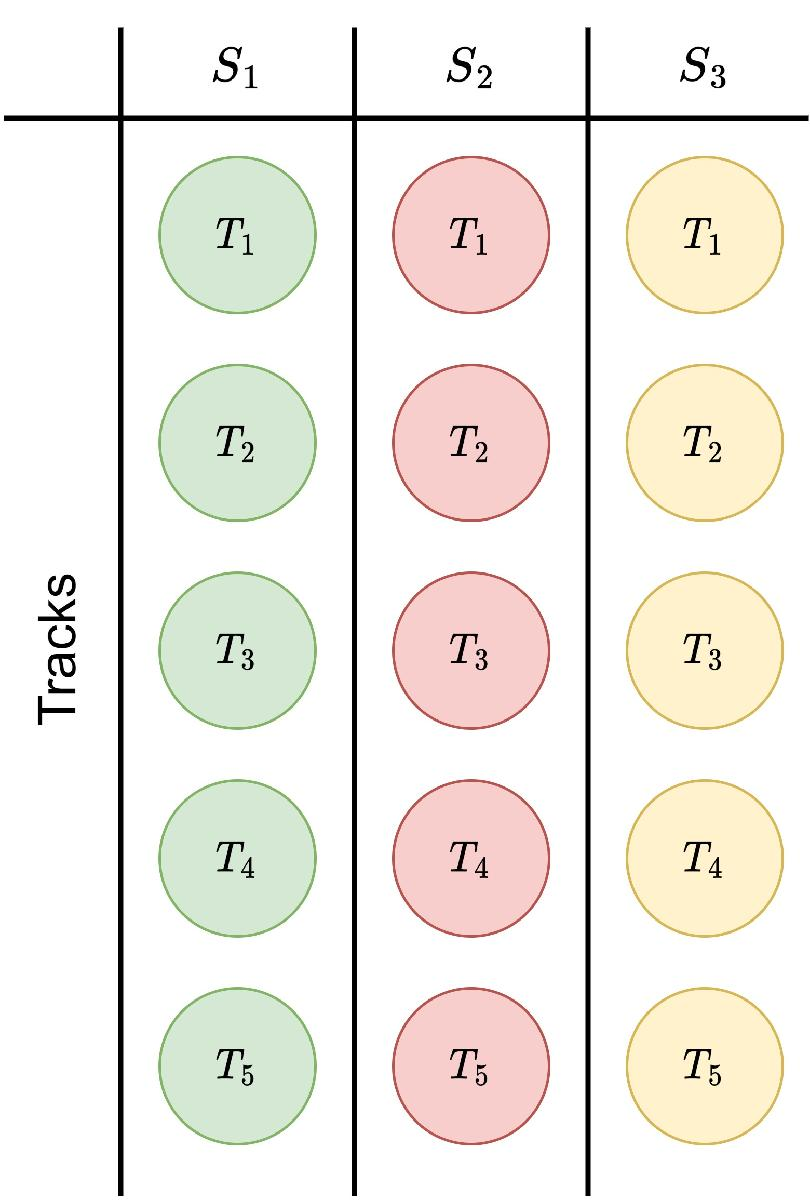

The sensor$-$track list shown in the Figure 1 is called *balanced list* because it contains the same number of tracks for each sensor originating from the same targets.

### Pairwise Assignments in the Balanced List Case

In this case, a $2$-D assignment problem is solved between a pair of sensors. Each such a problem requires the use of a $5$-by-$5$ cost matrix, where $5$ is the number of targets. A sequential pairwise approach is used such that we first consider pairing $S_1 - S_2$ and solve the $2$-D assignment problem, and then pairing $S_2$$-$$S_3$ and solve the resulting $2$-D assingment problem. Appending the output of both assignment problems gives an overall $S_1$$-$$S_2$$-$$S_3$ assignment list. Note that for this $S_1$$-$$S_2$$-$$S_3$ assignment list, the assignment between $S_1$$-$$S_3$ is indirect as opposed to the assignments $S_1$$-$$S_2$ and $S_2$$-$$S_3$.

Note that we can pick a different order of pairs to build the overall assignment, namely for example, pairing $S_1$$-$$S_3$ followed by pairing $S_2$$-$$S_3$. In this case, the $S_1$$-$$S_2$ assignment is indirectly computed. 

The problem is consistent if the order choice is immaterial. In that case, it is said that there are no transitivity errors.

In real world problems, the ground truth is not known for sure. However, in this simulation, the ground truth information we can use to compare the results is as follows:

T = table((1:numel(localTracks{1}))', vertcat(localTracks{1}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 1)', 'Corresponding Target ID'});
disp('Table 1'); disp(T);

Table 1
    Sensor-based Track Enumeration (Sensor 1)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "E"          
                        2                                  "D"          
                        3                                  "C"          
                        4                                  "B"          
                        5                                  "A"          



T = table((1:numel(localTracks{2}))', vertcat(localTracks{2}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 2)', 'Corresponding Target ID'});
disp('Table 2'); disp(T);

Table 2
    Sensor-based Track Enumeration (Sensor 2)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "D"          
                        2                                  "C"          
                        3                                  "B"          
                        4                                  "A"          
                        5                                  "E"          



T = table((1:numel(localTracks{3}))', vertcat(localTracks{3}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 3)', 'Corresponding Target ID'});
disp('Table 3'); disp(T);

Table 3
    Sensor-based Track Enumeration (Sensor 3)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "B"          
                        2                                  "E"          
                        3                                  "D"          
                        4                                  "C"          
                        5                                  "A"          



In the example below, we create $5$-by-$5$ cost matrices for the pairs $S_1$$-$$S_2$, $S_2$$-$$S_3$ and $S_1$$-$$S_3$. 

[balanced2Dcost, balancedCombinations] = generalized_likelihood_cost_2D(localTracks, true);
seqList = repmat([1, 2], 2, 1) + (0:1)';
indices = ismember(balancedCombinations, seqList, "rows");
seq2DCost = balanced2Dcost(indices);
transitivityCost = balanced2Dcost(~indices);

Then, we solve the optimization problem using created cost matrices by means of MILP solver.

for i = 1:numel(seq2DCost)
    balanced2Dassignments{i, 1} = milp_solver(seq2DCost{i}, "HasExtraRowsAndColumns", false);
end
for i = 1:numel(transitivityCost)
    balanced2DTransAssn{i, 1} = milp_solver(transitivityCost{i}, "HasExtraRowsAndColumns", false);
end

To see the results, $S_1$$-$$S_2$ pairwise assignment is as follows:

T = table(balanced2Dassignments{1}(:, 1), balanced2Dassignments{1}(:, 2), VariableNames = {'S_1', 'S_2'});
disp('Table 4'); disp(T);

Table 4
    S_1    S_2
    ___    ___

     1      1 
     3      2 
     4      3 
     5      4 
     2      5 



The $S_2$$-$$S_3$  pairwise assignment is as follows: 

balanced2Dassignments{2} = sortrows(balanced2Dassignments{2}, 1);
T = table(balanced2Dassignments{2}(:, 1), balanced2Dassignments{2}(:, 2), VariableNames = {'S_2', 'S_3'});
disp('Table 5'); disp(T);

Table 5
    S_2    S_3
    ___    ___

     1      3 
     2      4 
     3      1 
     4      5 
     5      2 



One may stop here, and **indirectly** (transitivity) conclude the $S_1$$-$$S_3$ assignments through $S_2$ as follows:

Table 6


$$\matrix{
S_1 & S_2 & S_3 \cr \hline
1 & 1 & 3 \cr
3 & 2 & 4 \cr
4 & 3 & 1 \cr
5 & 4 & 5 \cr
2 & 5 & 2
}$$


To directly determine the $S_1$$-$$S_3$ assignment, we use the optimal solver to compute the $2$-D assignment for the $S_1$$-$$S_3$ pair to get the following

T = table(balanced2DTransAssn{1}(:, 1), balanced2DTransAssn{1}(:, 2), VariableNames = {'S_1', 'S_3'});
disp('Table 7'); disp(T);

Table 7
    S_1    S_3
    ___    ___

     4      1 
     1      2 
     2      3 
     3      4 
     5      5 



To compare with the indirect $S_1$$-$$S_3$ of Table 7, sort all rows of Table 6 with respect to $S_3$ for easy comparison to obtain Table 8:

Table 8


$$\matrix{
S_1 & S_2 & S_3 \cr \hline
4 & 3 & 1 \cr
2 & 5 & 2 \cr
1 & 1 & 3 \cr
3 & 2 & 4 \cr
5 & 4 & 5
}$$


As can seen from Table 8, Track 2 of $S_3$ matches Track 2 of $S_1$ while in Table 7 it matches Track 1 of $S_1$. Similarly, Track 3 of $S_3$ matches Track 1 of $S_1$, while in Table 7 it matches Track 2 of $S_1$.

**Note that the resulting direct solution of Table 7 is inconsistent with the indirect solution of Table 8, thus having transitivity errors.**

### S-D Assignment in the Balanced List Case

By its very nature, $S$-D assignment algorithms perform assignment using concurrently all available multi-dimensional cost information. Therefore, for the same example from before of Table 1, Table 2 and Table 3, we perform $S$-D assignment using all of the $S_1$$-$$S_2$$-$$S_3$ lists concurrently.

balancedSDcost = generalized_likelihood_cost_SD(localTracks, true);
balancedSDassignments = milp_solver(balancedSDcost);

The assignment results is as follows

T = table(balancedSDassignments(:, 1), balancedSDassignments(:, 2), balancedSDassignments(:, 3), VariableNames = {'S_1', 'S_2', 'S_3'});
disp('Table 9'); disp(T);

Table 9
    S_1    S_2    S_3
    ___    ___    ___

     4      3      1 
     1      5      2 
     2      1      3 
     3      2      4 
     5      4      5 



Since Table 9 is computed directly, there are no indrect assignments to compare against, and thus no transitivity errors to worry about.

As on whether the assignment is consistent with the ground truth where the underlying target IDs of the associated tracks are also matching, we assume in this example that we learned later the ground truth information and now we are in retrospect assessing the performance of the assignments. In this case, one would need to look at Table 10.

T = table(vertcat(localTracks{1}(balancedSDassignments(:, 1)).ID), vertcat(localTracks{2}(balancedSDassignments(:, 2)).ID), vertcat(localTracks{3}(balancedSDassignments(:, 3)).ID), VariableNames = {'S_1', 'S_2', 'S_3'});
disp('Table 10'); disp(T);

Table 10
    S_1    S_2    S_3
    ___    ___    ___

    "B"    "B"    "B"
    "E"    "E"    "E"
    "D"    "D"    "D"
    "C"    "C"    "C"
    "A"    "A"    "A"



As can be seen from Table 10, each track tuple (rows of Table 10) indeed correspond to the same underlying physical target.

## Unbalanced List

Let us make our simulation more realistic by considering the case where somehow some of the sensors are not capable of generating tracks for all $5$ targets. This can occur in real scenarios due to different field of views, missed detections, or unresolved targets which will result in an *unbalanced list* as shown in the Figure 2.

Figure 2

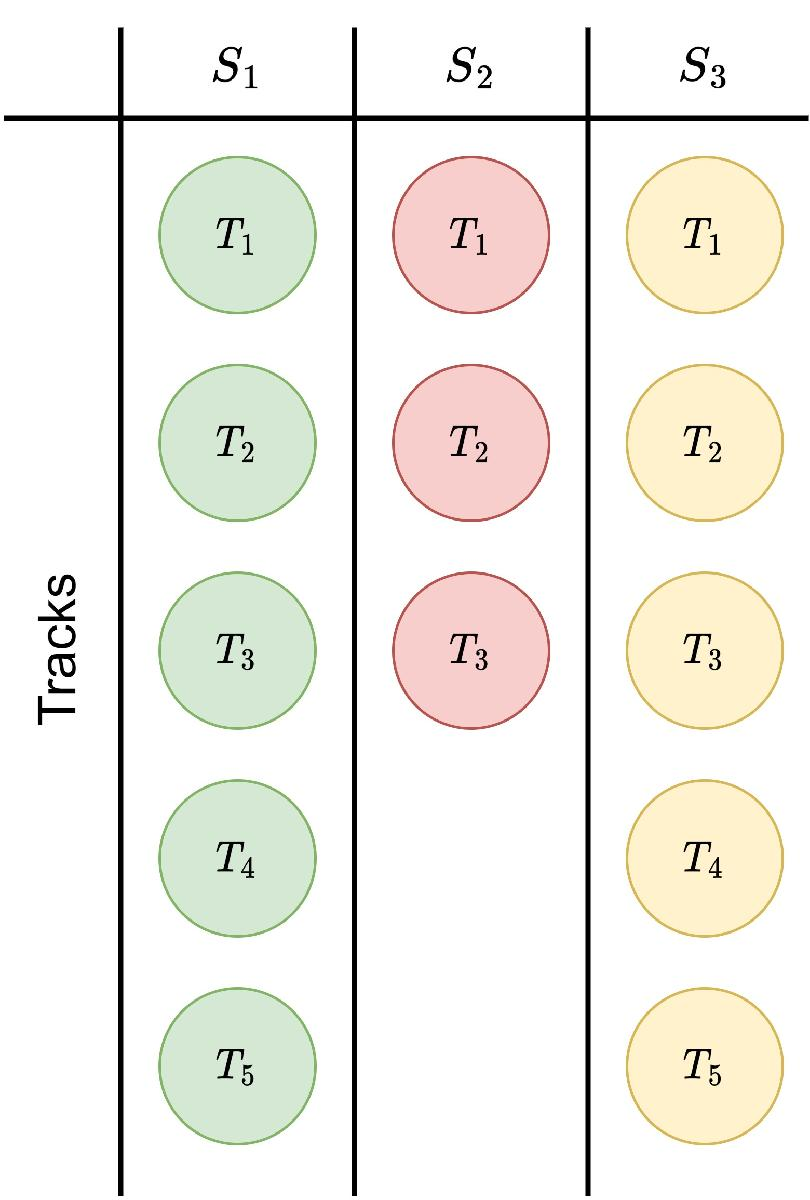

### Creating Unbalanced Scenario

In order to create an unbalanced scenario, let's delete some **random** tracks from Figure 1 which results in Figure 2.

keptTracks = {1:5, 1:5, 1:5};
deletedTracks = {};
unbalancedSensorNum = randi(3);
unbalancedSensors = randperm(3, unbalancedSensorNum);
for i = 1:unbalancedSensorNum
    unbalancedTargetNum = randi(4);
    unbalancedTargets = randperm(5, unbalancedTargetNum);
    ind = ismember(keptTracks{unbalancedSensors(i)}, unbalancedTargets);
    keptTracks{unbalancedSensors(i)}(ind) = [];
    deletedTracks{end + 1, 1} = unbalancedTargets;
    localTracks{unbalancedSensors(i)}(unbalancedTargets) = [];
end

The ground truth information we can use to compare the results is given in the following tables:

T = table((1:numel(localTracks{1}))', vertcat(localTracks{1}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 1)', 'Corresponding Target ID'});
disp('Table 11'); disp(T);

Table 11
    Sensor-based Track Enumeration (Sensor 1)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "E"          
                        2                                  "D"          
                        3                                  "C"          
                        4                                  "B"          
                        5                                  "A"          



T = table((1:numel(localTracks{2}))', vertcat(localTracks{2}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 2)', 'Corresponding Target ID'});
disp('Table 12'); disp(T);

Table 12
    Sensor-based Track Enumeration (Sensor 2)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "D"          
                        2                                  "C"          
                        3                                  "B"          



T = table((1:numel(localTracks{3}))', vertcat(localTracks{3}.ID), VariableNames = {'Sensor-based Track Enumeration (Sensor 3)', 'Corresponding Target ID'});
disp('Table 13'); disp(T);

Table 13
    Sensor-based Track Enumeration (Sensor 3)    Corresponding Target ID
    _________________________________________    _______________________

                        1                                  "B"          
                        2                                  "E"          
                        3                                  "D"          
                        4                                  "C"          
                        5                                  "A"          



### Pairwise Assignments in the Unbalanced List Case

Let's first create the cost matrices for the $2$-D assignment as we have done for the balanced scenario.

[unbalanced2Dcost, unbalancedCombinations] = generalized_likelihood_cost_2D(localTracks, false);
seqList = repmat([1, 2], 2, 1) + (0:1)';
indices = ismember(unbalancedCombinations, seqList, "rows");
seq2DCost = unbalanced2Dcost(indices);
transitivityCost = unbalanced2Dcost(~indices);

We can now solve the unbalanced list problem sequentially using the cost by means of MILP solver.

for i = 1:numel(seq2DCost)
    unbalanced2Dassignments{i, 1} = milp_solver(seq2DCost{i}, "HasExtraRowsAndColumns", true);
end
for i = 1:numel(transitivityCost)
    unbalanced2DTransAssn{i, 1} = milp_solver(transitivityCost{i}, "HasExtraRowsAndColumns", true);
end

To see the results, $S_1$$-$$S_2$ pairwise assignment is as follows: 

T = table(unbalanced2Dassignments{1}(:, 1), unbalanced2Dassignments{1}(:, 2), VariableNames = {'S_1', 'S_2'});
disp('Table 14'); disp(T);

Table 14
    S_1    S_2
    ___    ___

     1      0 
     5      0 
     2      1 
     3      2 
     4      3 



The $S_2$$-$$S_3$  pairwise assignment is as follows: 

unbalanced2Dassignments{2} = sortrows(unbalanced2Dassignments{2}, 1);
T = table(unbalanced2Dassignments{2}(:, 1), unbalanced2Dassignments{2}(:, 2), VariableNames = {'S_2', 'S_3'});
disp('Table 15'); disp(T);

Table 15
    S_2    S_3
    ___    ___

     0      2 
     0      5 
     1      3 
     2      4 
     3      1 



One may stop here, and **indirectly** (transitivity) conclude the $S_1$$-$$S_3$ assignments through $S_2$ as follows:

Table 16


$$\matrix{
S_1 & S_2 & S_3 \cr \hline
1 & 0 & - \cr
5& 0 & - \cr
2 & 1 & 3 \cr
3 & 2 & 4 \cr
4 & 3 & 1
}$$


The elements of "$-$" in above table express that there is uncertainty about assignments. The only information we have up to this point is the assignment of $S_1$$-$$S_2$ and the assignment of $S_2$$-$$S_3$ given above. How can one conclude the relationship between $S_1$$-$$S_3$ precisely using the two separate assignments between $S_1$$-$$S_2$ and $S_2$$-$$S_3$? As a heuristic approach, we will ignore the uncertainties and fill them with $0$ which indicates that there is no associated track in the corresponding list.

Table 17


$$\matrix{
S_1 & S_2 & S_3 \cr \hline
1 & 0 & 0 \cr
5 & 0 & 0 \cr
2 & 1 & 3 \cr
3 & 2 & 4 \cr
4 & 3 & 1\cr
0 & 0 & 2 \cr
0 & 0 & 5
}$$


To directly determine the $S_1 - S_3$ assignment, we use the optimal solver to compute the $2$-D assignment for the $S_1 - S_3$ pair to get the following

T = table(unbalanced2DTransAssn{1}(:, 1), unbalanced2DTransAssn{1}(:, 2), VariableNames = {'S_1', 'S_3'});
disp('Table 18'); disp(T);

Table 18
    S_1    S_3
    ___    ___

     4      1 
     1      2 
     2      3 
     3      4 
     5      5 



**Note that the resulting direct solution of Table 18 is inconsistent with the indirect solution of Table 17, thus having transitivity errors.**

### S-D Assignment in the Unbalanced List Case

For the unbalanced scenario, first a multidimensional cost will be generated and solved concurrently using all the information available at the time by means of MILP solver.

unbalancedSDcost = generalized_likelihood_cost_SD(localTracks, false);
unbalancedSDassignments = milp_solver(unbalancedSDcost, "HasExtraRowsAndColumns", true);

As emphasized for the balanced case, by its very nature, $S$-D assignment algorithms perform assignment using all available multi-dimensional cost information. Therefore, for the same example from before of Table 11, Table 12 and Table 13, we perform $S$-D assignment using all of the $S_1$$-$$S_2$$-$$S_3$ lists concurrently. The $S_1$–$S_2$–$S_3$ assignment provided by $S$-D assignment algorithm is as follows:

T = table(unbalancedSDassignments(:, 1), unbalancedSDassignments(:, 2), unbalancedSDassignments(:, 3), VariableNames = {'S_1', 'S_2', 'S_3'});
disp('Table 19'); disp(T);

Table 19
    S_1    S_2    S_3
    ___    ___    ___

     4      3      1 
     2      0      2 
     1      1      3 
     3      2      4 
     5      0      5 



IDs = strings(size(unbalancedSDassignments)); % 3-sensor & 5-target at most
for i = 1:size(unbalancedSDassignments, 2)
    for j = 1:size(unbalancedSDassignments, 1)
        if unbalancedSDassignments(j, i) ~= 0
            IDs(j, i) = localTracks{i}(unbalancedSDassignments(j, i)).ID;
        else
            IDs(j, i) = "-";
        end
    end
end
T = table(IDs(:, 1), IDs(:, 2), IDs(:, 3), VariableNames = {'S_1', 'S_2', 'S_3'});
disp('Table 20'); disp(T);

Table 20
    S_1    S_2    S_3
    ___    ___    ___

    "B"    "B"    "B"
    "D"    "-"    "E"
    "E"    "D"    "D"
    "C"    "C"    "C"
    "A"    "-"    "A"



The $S$-D assignment algorithm never contains transitivity error. Nevertheless, depending on the cost matrix used, it may produce an faulty solution.  As can be seen in Table 20, only list $S_1$ has an switch incorrectly between $D$ and $E$ assignments.

## References

[1]    L. M. Kaplan, Y. Bar-Shalom and W. D. Blair, "Assignment costs for multiple sensor track-to-track association," in *IEEE Transactions on Aerospace and Electronic Systems*, vol. 44, no. 2, pp. 655-677, April 2008, doi: 10.1109/TAES.2008.4560213.

## Utility Functions

function likelihood = generalized_neg_loglikelihood(localTracks, hypothesis)
    arguments
        localTracks (:, 1) cell
        hypothesis (1, :) {mustBeInteger, mustBeNonnegative}
    end
    ind = find(hypothesis ~= 0);
    tempCost = 0;
    Rfn = zeros(2, 2);
    xfn = zeros(2, 1);
    for k = 1:numel(ind)
        trackPair1 = localTracks{ind(k)}(hypothesis(ind(k)));
        Ri = trackPair1.StateCovariance;
        Rfn = Rfn + inv(Ri);
    end
    Rfn = inv(Rfn);
    for k = 1:numel(ind)
        trackPair1 = localTracks{ind(k)}(hypothesis(ind(k)));
        xi = trackPair1.State;
        Ri = trackPair1.StateCovariance; 
        xfn = xfn + inv(Ri) * xi;
    end
    xfn = Rfn * xfn;
    for k = 1:numel(ind)
        trackPair1 = localTracks{ind(k)}(hypothesis(ind(k)));
        tempCost = tempCost + log(1 / (sqrt(det(2 * pi * trackPair1.StateCovariance)))) - (0.5 * ((trackPair1.State - xfn)') * inv(trackPair1.StateCovariance) * (trackPair1.State - xfn));
    end
    likelihood = -tempCost;
end

function cost = generalized_likelihood_cost_SD(localTracks, isBalanced)
    arguments
        localTracks (:, 1) cell
        isBalanced (1, 1) logical = true
    end
    dim = numel(localTracks);
    trackNum = zeros(1, dim);
    for i = 1:dim
        trackNum(i) = size(localTracks{i}, 1);
    end
    if isBalanced
        cost = Inf(trackNum);
        startInd = 1;
    else
        trackNum = trackNum + 1;
        cost = Inf(trackNum);
        cost(1) = 0;
        startInd = 2;
    end
    subIndices = cell(dim, 1);
    [subIndices{:}] = ind2sub(size(cost), 1:numel(cost));
    hypotheses = vertcat(subIndices{:})';
    for i = startInd:size(hypotheses, 1)
        tupleArr = hypotheses(i, :) - double(~isBalanced);
        tuple = num2cell(hypotheses(i, :));
        loglikelihood = generalized_neg_loglikelihood(localTracks, tupleArr);
        if ~isBalanced
            dummies = find(tupleArr == 0);
            if ~isempty(dummies)
                coeff = 0;
                for k = 1:numel(dummies)
                    coeff = coeff + numel(localTracks{dummies(k)});
                end
                loglikelihood = loglikelihood * coeff;
            end
        end
        cost(tuple{:}) = loglikelihood;
    end
end

function [cost, combinations] = generalized_likelihood_cost_2D(localTracks, isBalanced)
    arguments
        localTracks (:, 1) cell
        isBalanced (1, 1) logical = true;
    end
    dim = numel(localTracks);
    combinations = sortrows(nchoosek(1:dim, 2), 1);
    cost = cell(size(combinations, 1), 1);
    for i = 1:size(combinations, 1)
        trackNum = [numel(localTracks{combinations(i, 1)}), numel(localTracks{combinations(i, 2)})];
        if isBalanced
            cost{i} = Inf(trackNum);
            startInd = 1;
        else
            trackNum = trackNum + 1;
            cost{i} = Inf(trackNum);
            cost{i}(1) = 0;
            startInd = 2;
        end
        subIndices = cell(2, 1);
        [subIndices{:}] = ind2sub(size(cost{i}), 1:numel(cost{i}));
        hypotheses = vertcat(subIndices{:})';
        for j = startInd:size(hypotheses, 1)
            tupleArr = hypotheses(j, :) - double(~isBalanced);
            tuple = num2cell(hypotheses(j, :));
            loglikelihood = generalized_neg_loglikelihood(localTracks(combinations(i, :)), tupleArr);
            if ~isBalanced
                dummies = find(tupleArr == 0);
                if ~isempty(dummies)
                    coeff = 0;
                    for k = 1:numel(dummies)
                        coeff = coeff + numel(localTracks{dummies(k)});
                    end
                    loglikelihood = loglikelihood * coeff;
                end
            end
            cost{i}(tuple{:}) = loglikelihood;
        end
    end
end

function [assignments, achievedCost, exitFlag, output] = milp_solver(cost, options)
    arguments
        cost {mustBeReal}
        options.HasExtraRowsAndColumns (1, 1) logical = false;
    end
    % Identify Problem Specific Numbers
    [sz, dim, elementNum, constraintNum] = get_numbers(cost, options.HasExtraRowsAndColumns);

    % Identify intlinprog parameters
    f = reshape(cost, [elementNum, 1]);
    intcon = 1:elementNum;
    A = [];
    b = [];
    Aeq = zeros(constraintNum, elementNum);
    beq = ones(constraintNum, 1);
    lb = zeros(elementNum, 1);
    ub = ones(elementNum, 1);
    x0 = [];
    opt = optimoptions("intlinprog", "Display", "off", ...
                       "RootLPAlgorithm", "primal-simplex");

    % Modify Initialized Aeq
    constraintCounter = 1;
    hypotheses = get_hypotheses(sz) - double(options.HasExtraRowsAndColumns);
    for i = 1:dim
        hypo = hypotheses(:, i);
        for j = 1:max(hypo)
            ind = (hypo == j);
            Aeq(constraintCounter, ind) = 1;
            constraintCounter = constraintCounter + 1;
        end
    end
    
    % Solve the problem
    [assignments, achievedCost, exitFlag, output] = intlinprog(f, intcon, A, b, Aeq, beq, lb, ub, x0, opt);
    assn = cell(dim, 1);
    [assn{:}] = ind2sub(sz, find(assignments == 1));
    assignments = horzcat(assn{:});
    if options.HasExtraRowsAndColumns
        assignments = assignments - 1;
    end
end

function [sz, dimension, elementNum, constraintNum] = get_numbers(cost, hasExtraRowsAndColumns)
    arguments
        cost {mustBeReal}
        hasExtraRowsAndColumns (1, 1) logical
    end
    sz = size(cost);
    dimension = numel(sz);
    elementNum = numel(cost);
    constraintNum = sum(sz) - dimension * double(hasExtraRowsAndColumns);
end

function hypotheses = get_hypotheses(sz)
    arguments
        sz (1, :) {mustBeInteger, mustBePositive}
    end
    cost = zeros(sz);
    dim = numel(sz);
    subIndices = cell(dim, 1);
    [subIndices{:}] = ind2sub(sz, 1:numel(cost));
    hypotheses = vertcat(subIndices{:})';
end